# Programmatic App That Displays a Table

This example shows how to display a table in an app using the `uitable` function. It also shows how to modify the appearance of the table and how to restrict editing of the table in the running app.

## Create a Table UI Component Within a Figure

The `uitable` function creates an empty UI table in the figure.

fig = uifigure('Position',[100 100 752 250]);
uit = uitable('Parent',fig,'Position',[25 50 700 200]);

## Create a Table Containing Mixed Data Types

Load sample patient data that contains mixed data types and store it in a table array. To have data appear as a drop-down list in the cells of the table component, convert a cell array variable to a categorical array. To display the data in the table UI component, specify the table array as the value of the `Data` property.

load patients
t = table(LastName,Age,Weight,Height,Smoker, ...
          SelfAssessedHealthStatus);
t.SelfAssessedHealthStatus = categorical(t.SelfAssessedHealthStatus, ...
          {'Poor','Fair','Good','Excellent'},'Ordinal',true);

uit.Data = t;

## Customize the Display

You can customize the display of a UI table in several ways. Use the `ColumnName` property to add column headings.

uit.ColumnName = {'Last Name','Age','Weight', ...
                  'Height','Smoker','Health Status'};

To adjust the widths of the columns, specify the `ColumnWidth` property. The `ColumnWidth` property is a 1-by-N cell array, where N is the number of columns in the table. Set a specific column width, or use `'auto'` to let MATLAB® set the width based on the contents.

uit.ColumnWidth = {'auto',75,'auto','auto','auto',100};

Add numbered row headings by setting the `RowName` property to `'numbered'`.

uit.RowName = 'numbered';

Reposition and resize the table using the `Position` property.

uit.Position = [15 25 565 200];

By default, table UI components use row striping and cycle through the specified background colors until the end of the table is reached. If you set the `RowStriping` property to `'off'`, the table UI component will just use the first color specified in the `BackgroundColor` property for all rows. Here, leave row striping `'on'` and set three different colors for the `BackgroundColor` property.

uit.BackgroundColor = [1 1 .9; .9 .95 1;1 .5 .5];

## Enable Column Sorting and Restrict Editing of Cell Values

To restrict the user's ability to edit data in the table, set the `ColumnEditable` property. By default, data cannot be edited in the running app. Setting the `ColumnEditable` property to `true` for a column allows the user to edit data in that column.

uit.ColumnEditable = [false true true true true true];

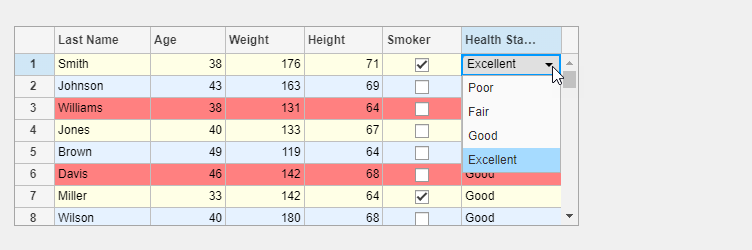

Make all the columns sortable by setting the `ColumnSortable` property to `true`. If a column is sortable, arrows appear in the header when you hover your mouse over it.

uit.ColumnSortable = true;

## Create a Callback

To program the table to respond to user interaction, create a callback function. For example, you can specify a `SelectionChangedFcn` to execute commands when the app user selects a different row, column, or cell of the table. 

Here, write a callback function to validate that the values in the `Age` column are between 0 and 120. Create a new function named `ageCheckCB` and save it to a file named `ageCheckCB` in a folder that is on the MATLAB path.

Assign the `ageCheckCB` to the `CellEditCallback` property. This callback executes when the user changes a value in a cell. If the user enters a value that is outside the acceptable range, the callback function returns a warning and sets the cell value back to the previous value.

uit.CellEditCallback = @ageCheckCB;

For more information about writing callback functions, see [Write Callbacks for Apps Created Programmatically](docid:creating_guis#f16-999606).

## Get All Table Properties

To see all the properties of the table, use the `get` command.

get(uit)

*Copyright 2020 The MathWorks, Inc.*